%% Project 14: ECG / Signal Noise Filtering Demo
% This script demonstrates generating a noisy ECG-like signal, applying a
% moving-average smoothing filter, and comparing raw vs filtered signals.
%{
ES115 ECG / Signal Noise Filtering Demo
 originally from Module 3: Project Bank - 02/02/2026
Author: Gracy Sylvestre
Version: 2.0
Date: 2026-04-25
State the problem (Purpose):
 Demonstrate cleaning a noisy signal and comparing results

Describe input values (Knowns)and required output (Unknowns) 
    Input: - moving average window size
           - time
           - period
    Output:
        - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
       - table of usage values and corresponding bills for both plans
      - intersection point where both bills cost the same
      - plan reccomendations specific to usage value of choice
     
  Engineering Workflow and Algarithems:
   - Piecewise linear modeling
    - Numerical Vectorization 
    - Comparison Logic and Thresholding

MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
    -  if/else/end 
    - plot function
    - table function
    - fprintf
 %}

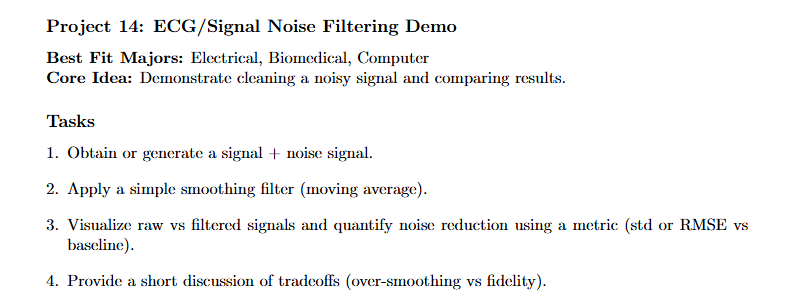


clear; clc; close all; %clear workspace

% user input

fprintf("ECG Noise Filtering Demo\n");   %display system title 

ECG Noise Filtering Demo


windowsize = input("Enter moving average window size (odd number, recommended 5–15): "); %user choice of window size

if isempty(windowsize)
    windowSize = 9; % default window size if user presses ENTER
end

## Task 1 : Obtain or generate signal + noise signal


time = 0:0.001:1; %vector for time
  T = 1/1.3;       % 1.3 Hz period
  phase = mod(time, T)/T;          % normalized phase 0..1
  saw = 2*(phase < 0.5).*(phase) + (2*(phase-1)).*(phase>=0.5); % symmetric saw
  cleanECG = 1.2 * saw;
noise = 0.35*randn(size(time));               % Gaussian noise
noisyECG = cleanECG + noise;

## Task 2: Apply a simple smoothing filter (moving average)

% movingAverageFilter
function y = movingAverageFilter(x, N) % Applies an N-point moving average filter to input vector x.

% Inputs:
%   x = input signal
%   N = window size 
% Output:
%   y = filter output signal

y = zeros(size(x));
L = length(x);
half = floor(N/2);

for i = 1:L % handle edges %subset window valid 
    left = max(1, i-half);
    right = min(L, i+half);
    y(i) = mean(x(left:right));
end
end


function e = RMSE(a, b) % Root Mean Square Error between two signals
e = sqrt(mean((a - b).^2));
end

filteredECG = movingAverageFilter(noisyECG, windowsize);   %filter smooth by moving average 


## Task 3: Visualize raw vs filtered signals and quantify noise reduction using a metric (std or RMSE vs baseline)

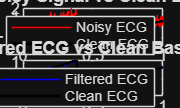

rmse_raw = RMSE(noisyECG, cleanECG);
rmse_filt = RMSE(filteredECG, cleanECG);

figure;  %create first subplot
subplot(2,1,1);
plot(time, noisyECG, 'r'); hold on;  %plot noisy signal in red
plot(time, cleanECG, 'k', 'LineWidth', 1.4); %plot clean baseline in black line 
title("Raw Noisy Signal vs Clean Baseline"); %title the graph
xlabel("Time (s)"); ylabel("Amplitude"); %label horizontal and vertical axis 
legend("Noisy ECG","Clean ECG", "Location", "northeast"); % display legend in top right corner

subplot(2,1,2); %create second subplot
plot(time, filteredECG, 'b'); hold on;    %plot filtered signal in blue
plot(time, cleanECG, 'k', 'LineWidth', 1.4);  %plot clean baseline in black line
title("Filtered ECG vs Clean Baseline"); % title the graph
xlabel("Time (s)"); ylabel("Amplitude"); % label horizonta; and vertical axis 
legend("Filtered ECG","Clean ECG", "Location","southeast"); %display legend in bottom right corner


% noise reduction quantification using metrics
fprintf("\n   Noise Reduction Metrics:    \n");   %display title of metrics


   Noise Reduction Metrics:    


fprintf("RMSE (Raw vs Clean):       %.4f\n", rmse_raw); %display raw vs clean RMSE

RMSE (Raw vs Clean):       0.3487


fprintf("RMSE (Filtered vs Clean):  %.4f\n", rmse_filt); %display filtered vs clean Rmse

RMSE (Filtered vs Clean):  0.1299



% testing windows 
testWindows = [3:2:25];  % 3 to 25 going by values of 2
fprintf("\nTesting multiple window sizes:\n");  %create loop to test multiple odd numbered windows and its RMSE


Testing multiple window sizes:



for w = testWindows   %set up test window values
    filtTest = movingAverageFilter(noisyECG, w); 
    testRMSE = RMSE(filtTest, cleanECG);  %set up RMSE test values 
    fprintf("Window %2d → RMSE = %.4f\n", w, testRMSE); %display window sizes alongside RMSE numbers
end

Window  3 → RMSE = 0.2066
Window  5 → RMSE = 0.1648
Window  7 → RMSE = 0.1447
Window  9 → RMSE = 0.1341
Window 11 → RMSE = 0.1283
Window 13 → RMSE = 0.1247
Window 15 → RMSE = 0.1231
Window 17 → RMSE = 0.1232
Window 19 → RMSE = 0.1247
Window 21 → RMSE = 0.1266
Window 23 → RMSE = 0.1280
Window 25 → RMSE = 0.1299


 
testingtable = table(w , testRMSE, ...
    'VariableNames', {'Window','RMSE'}) %create table with rsme values

testingtable = 1×2 table
    Window     RMSE  
    ______    _______

      25      0.12989


## Step 4: Provide a short discussion of tradeoffs (over-smoothing vs fidelity).

fprintf("\n       Discussion:      \n");


       Discussion:      


fprintf(" Larger window sizes cause increased noise reduction while distorting sharp ECG features.\n");

 Larger window sizes cause increased noise reduction while distorting sharp ECG features.


fprintf(" Small windows preserve detail while leaving more noise \n");

 Small windows preserve detail while leaving more noise 


%{ 
Reflection After Completing the Project:
- What do slope and intercept represent for each plan?
  The intercept of plan A represents the initial service cost of $25 while
  the slope is reflective of the cost rate of $15/kwh. Similarly, the
  intercept of plan B's first section reflects an initial customer charge
  of $40 and its slope is the cost increase at a rate of $12/kwh. Plan b's
  second region slope represents the cost increase rate of $14/kwh with an
  intercept that showcases the adjustment in customer charge in order to
  continue service after 400 kwh. 

- How does the piecewise structure change decision-making?
The piecewise structure affects decision making as customers are able to
benefit from the discounted offer with energy usage at 400 kwh and below. 

- What did you learn?
 Throughout my completion of this project, I was able to work on and
    add to the many tools and techniques that matlab has to offer. Going
    into this course matlab was an unfamilar resource to me and despite all
    of the research that had went into the weeks prior for preperatio of
    thius project, I still felt somewhat unprepared. Despite that, this
    project has allowed me to test different functions that I haven't been
    able to throuroughly utilize in the past such as, fprintf, table
    functions, intersection values on a graph, etc. 
 
  - What could be done differently?
many features among this project couldv'e been done differently such as including a user input system, testing more functions, etc. 
   
- Rate the project (1 - 10) (1 - represents simple and 10 represents difficult) 
   Rate : 6 
The most difficult thing about these projects is knowing where to begin,
especially when you are extremely unfamilar with the technology at hand.
However, the use of if/else statements allowed me to power through what I
felt was the most difficult section of this project.